load data\signal_1_wood_saw_decaying_pulse.mat

x=Basic_reading_Machine_1_Vibro_1(:,2)';

fs=Basic_reading_Machine_1_Vibro_1_metadata.SamplingRate

fs = 25000

dt=1/fs

dt = 4.0000e-05


n=length(x)

n = 350000


t=(0:n-1).*dt;

Time Waveform (TW)    (high pass filter maye?)

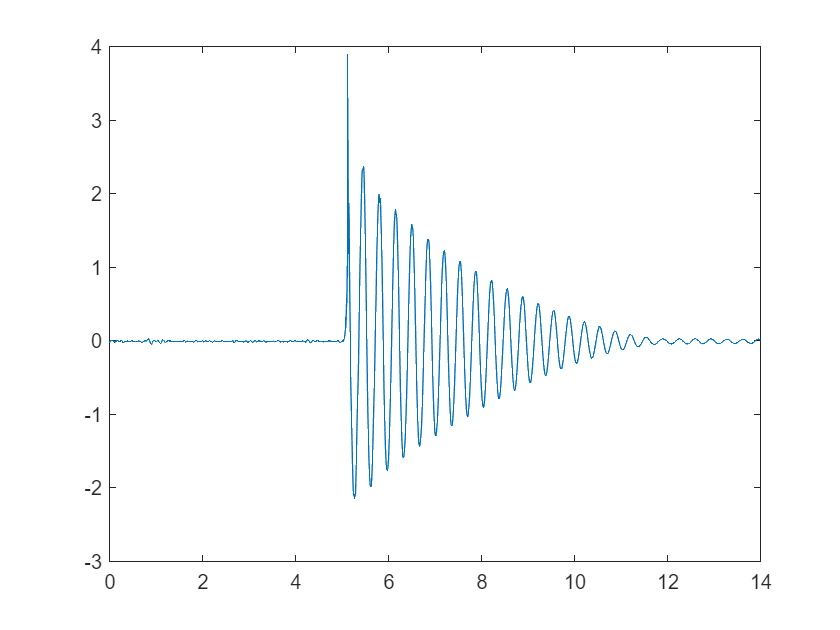



plot(t,x)



X=fft(x);
% X=ftt(x,2^19);
% n=2^19

mag=abs(X);
df=(fs/n)

df = 0.0714

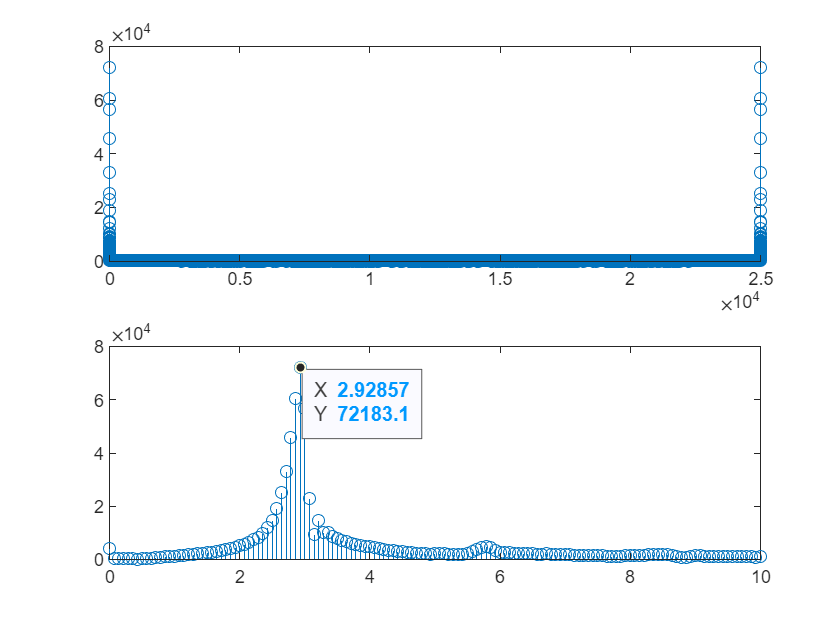

f=df*(0:n-1);
figure
subplot(2,1,1)
stem(f,mag')
subplot(2,1,2)
stem(f,mag')
xlim([0,10])

subplot(2,1,2)
ax = gca;
chart = ax.Children(1);
datatip(chart,2.929,7.218e+04);

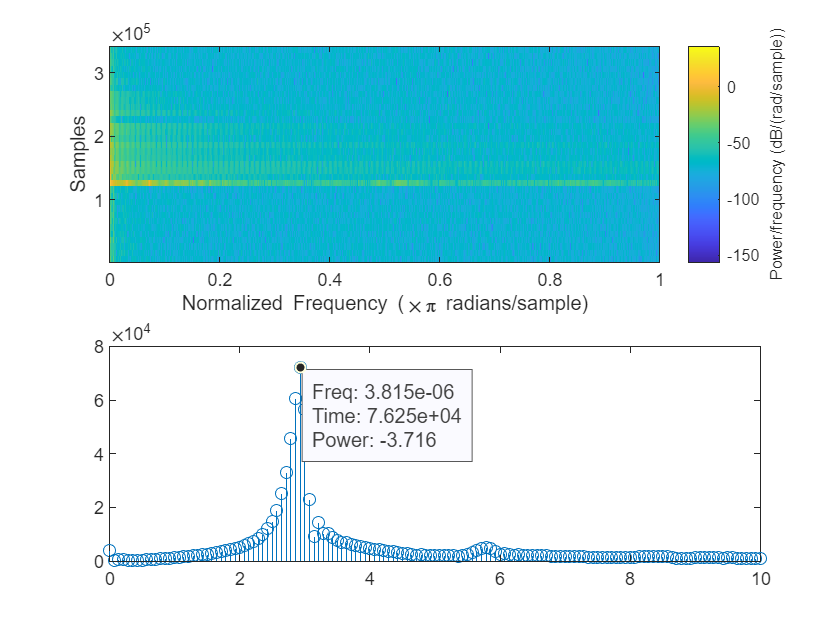

pwelch(x,fs)
% spectrogram(x,fs)
spectrogram(x,0.5*fs,0.1*fs,2^19)